## Kalman Filter with Constant Acceleration

In this example we use Kalman filter on a model that tracks position and velocity within a single axis of motion.

Acceleration will be the input, which is why this model is also known as *constant acceleration *(we don't update the acceleration, it is provided as an input used to update velocity and position).

### Initial State

Our initial state will be represented by *x0 *(the state at iteration zero), starting out with 0 for position and 0 for velocity.

x0 = [ ...
    0;      % position
    0;      % velocity
];

### State Matrix

The *state transition* matrix *C* looks like this for Newtonian dynamics:

timeStep = 0.25;

C = [...
    1, timeStep; % pos = pos * 1 + vel * timeStep
    0, 1         % vel = pos * 0 + vel * 1
];

Multiplying the system state by this matrix will increment the position by velocity scaled by time step, and leave the velocity unchanged.

### Input Matrix

The *input*, or *control* matrix *D* looks like this for a constant acceleration model:

D = [...
    0.5 * timeStep^2; % pos = pos + 0.5 * acc * timeStep^2
    timeStep;         % vel = vel + acc * timeStep
];

Multiplying the input by this matrix will update position and velocity according to the Newtonian equations of motion for constant acceleration.

Position will be incremented by half of acceleration scaled by time step squared, and velocity will be incremented by acceleration scaled by time step.

### Input

The input is a scalar, our acceleration. This could come from accelerometer (IMU) or tracking the position of the accelerator pedal of a moving behicle.

### Initial Covariance

For systems with more than one state variable, the variance is represented by a square matrix called "covariance".

Initial covariance *P0* (covariance at iteration zero) can be calculated like this for a constant acceleration model using the *var* and *covar* functions in Matlab that can operate on vectors of data samples:

The diagonal of this matrix encodes the variances of state variables (in this case position and velocity) and off-diagonal terms encode covariance of all state variables to all other state variables.

Since we don't have velocity measurements available in this example, we'll guess that position and velocity might be off by +/- ~22 meters per second squared which is reasonable for a large object.

To use this same variance for both position and velocity, we multiply it by a 2x2 identity matrix, which is called "projecting". This represents that both position and velocity could be off by +/- 22, and since the off-diagonal cells will contain zeros, we are also saying that position and velocity are not related.

While this isn't accurate, it's a good enough starting point that will let the Kalman filter work its magic to converge on something that is accurate over time.

% Accelerometer may be off by 44.7214m/s^2 (or +/- 22.3607m/s^2)
initialVariance = (44.7214 / 2)^2;

% Project variance into covariance
P0 = eye(length(x0)) * initialVariance;

### Noise Matrix

The process *noise* or *disturbance* matrix *Q* looks like this for a system with two state variables, position and velocity:

For a Newtonian system the relationships between position, velocity, and acceleration are known because they are given by equations of motion.

This lets us multiply a matrix filled with factors that represent these relationships by acceleration variance. In other words, we can project the variance of acceleration input into a covariance matrix. This is like saying "an acceleration input that's off by this many meters per second squared would result in position being off by this amount and acceleration being off by this amount".

accelerationVariance = 0.1^2;

Q = [...
    timeStep^4/4, timeStep^3/2;
    timeStep^3/2, timeStep^2;
] * accelerationVariance;

### Measurement Matrix

In this example our measurement is position in meters. The *H* measurement matrix represents how the system state maps to the measurement(s). This matrix has as many rows as there are measurements, and as many columns as there are state variables.

Since the output of our system model is position, and position is also the first state variable, we represent this as follows:

H = [ 1, 0 ]; % model output = position * 1 + velocity * 0

Multiplying system state by this matrix will simply extract the position from the state (the contribution of position to measurement is 100% and contribution of velocity to measurement is 0%).

### Measurement Variance

We only have one measurement (the position). To represent the certainty of single measurement we can use variance (a scalar) instead of coveriance (a square matrix). We call this *R*.

In this example we assume a constant measurement variance, meaning the device that measures position is equally accurate regardless of conditions.

% Position measurement may be off by as much as 20 meters, or +/- 10 meters
R = (10 * 2)^2;

### Filter

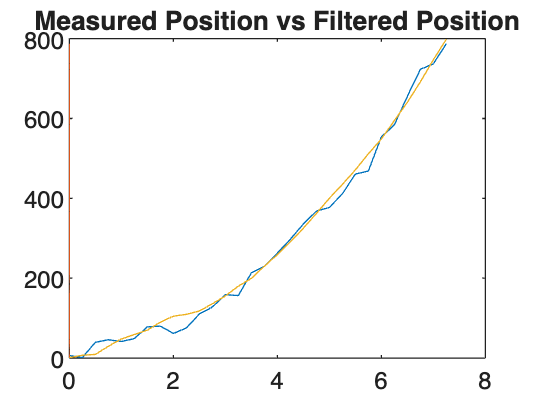

% Acceleration: our input (sampled every 0.25s)
inputs = [ ...
    39.81, ...
    39.67, ...
    39.81, ...
    39.84, ...
    40.05, ...
    39.85, ...
    39.78, ...
    39.65, ...
    39.67, ...
    39.78, ...
    39.59, ...
    39.87, ...
    39.85, ...
    39.59, ...
    39.84, ...
    39.90, ...
    39.63, ...
    39.59, ...
    39.76, ...
    39.79, ...
    39.73, ...
    39.93, ...
    39.83, ...
    39.85, ...
    39.94, ...
    39.86, ...
    39.76, ...
    39.86, ...
    39.74, ...
    39.94
] + g;

% Position: our measurement (sampled every 0.25s)
measurements = [ ...
    6.43, ...
    1.3, ...
    39.43, ...
    45.89, ...
    41.44, ...
    48.70, ...
    78.06, ...
    80.08, ...
    61.77, ...
    75.15, ...
    110.39, ...
    127.83, ...
    158.75, ...
    156.55, ...
    213.32, ...
    229.82, ...
    262.80, ...
    297.57, ...
    335.69, ...
    367.92, ...
    377.19, ...
    411.18, ...
    460.70, ...
    468.39, ...
    553.90, ...
    583.97, ...
    655.15, ...
    723.09, ...
    736.85, ...
    787.22
];

outputs = zeros(length(inputs));
time = zeros(length(inputs));
gains = zeros(length(inputs));
errors = zeros(length(inputs));

% Square identity matrix
I = eye(length(x0));

% Initial time
t = 0;

% Initial state
x = x0;

% Initial covariance
P = P0;

% Initial input
u = 0;

for i = 1:length(inputs)
    % Get input
    u = inputs(i);

    % Take measurement
    z = measurements(i);

    % Update state
    x = C * x + D * u;

    % Predict
    prediction = H * x;

    % Update covariance
    P = C * P * C' + Q;
    
    % Optimize gain
    K = (P * H') / (H * P * H' + R);

    % Correct state with measurement
    x = x + K * (z - prediction);

    % Correct covariance
    P = (I - K * H) * P * (I - K * H)' + K * R * K';

    % Output
    outputs(i) = prediction;
    time(i) = t;
    gains(i) = sum(K);
    t = t + timeStep;
end

plot(time, measurements, time, outputs);
title('Measured Position vs Filtered Position');

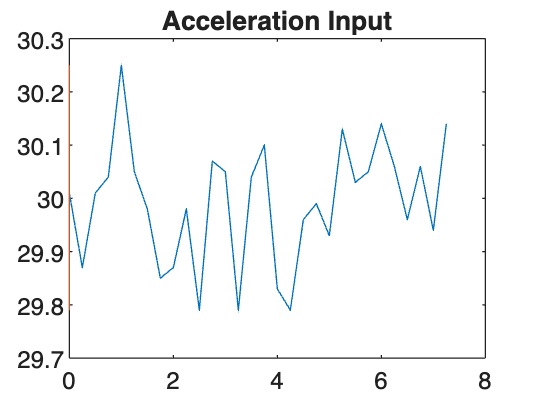


plot(time, inputs);
title('Acceleration Input');

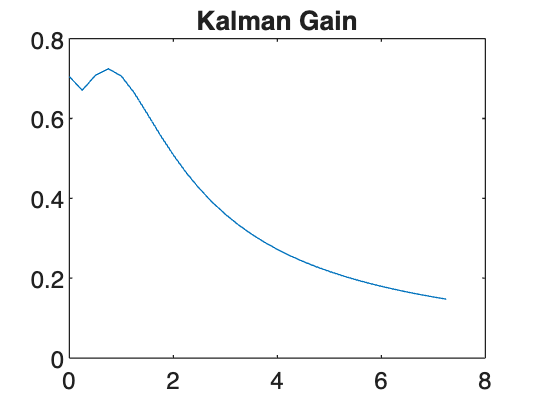


plot(time, gains);
title('Kalman Gain');